# HW3

clc;clear;close all;
% syms l1 l2 h m1 m2 m_d4 M g theta1 theta2 d4 dtheta1 dtheta2 dd4
% q=[theta1 theta2 d4];
% q_dot=[dtheta1 dtheta2 dd4];
global l2 h m1 m2 m_d4 M g rho d l
rho= 7800;
d=0.015;
l=0.2;
l2=0.2; 
h=0.1; 
g=9.81;
M=0.5;
m1=pi*d^2/4*h*rho;
m2=pi*d^2/4*l2*rho;
m_d4=pi*d^2/4*l*rho; 
para=[m1 m2 m_d4 M g h l2 l ];
q = rand(1,3);
q_dot = rand(1,3);
[H,C,G] = dynamics_mat(q,q_dot,para);
disp(H);disp(C);disp(G);

    0.0115   -0.0000   -0.0000
   -0.0000    0.4496    0.1551
   -0.0000    0.1551    0.7757

   -0.0207   -0.0297   -0.0048
    0.0297    0.2793    0.1910
    0.0048   -0.1910         0

    0.8547
   -2.8953
   -0.5744



## Q2

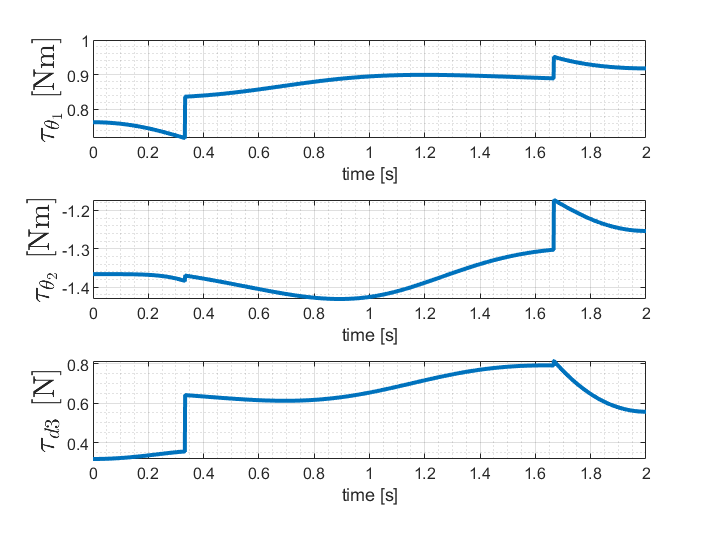


T = 2;
n = 2000;

% disp('>>Calculating tau values based on current configuration...');
tao=zeros(3,2000);
tau = tau_plan(T, n);    


t = linspace(0, T, n);


figure(1)
subplot(3,1,1)
plot(t,tau(1,:),'linewidth',2)
grid on; grid minor;
xlabel('time [s]')
ylabel('$\tau_{\theta_1}$ [Nm]','interpreter','latex','fontsize',15)
subplot(3,1,2)
plot(t,tau(2,:),'linewidth',2)
grid on; grid minor;
xlabel('time [s]')
ylabel('$\tau_{\theta_2}$ [Nm]','interpreter','latex','fontsize',15)
subplot(3,1,3)
plot(t,tau(3,:),'linewidth',2)
grid on; grid minor;
xlabel('time [s]')
ylabel('$\tau_{d3}$ [N]','interpreter','latex','fontsize',15)
saveas(gcf, 'q2','png')

## Q3

clc;clear;close all;
global l2 l3 h m1 m2 m_d4 M g rho d l
rho= 7800;
d=0.015;
l=0.2;
l2=0.2; 
h=0.1; 
g=9.81;
M=0.5;
m1=pi*d^2/4*h*rho;
m2=pi*d^2/4*l2*rho;
m_d4=pi*d^2/4*l*rho; 
para=[m1 m2 m_d4 M g h l2 l ];

PROFILE = 'trapezoidal';
T = 2;
n = 200;
h = 0.1;
l2 = 0.2;
l3 = 0;
params = [h,l2,l3];
x_init = [0.1, 0.2, 0.35]';
x_fin = [0.3, -0.1, 0.15]';
x = x_plan(PROFILE, T, n, x_init, x_fin);
v = v_plan(PROFILE, T, n, x_init, x_fin);
a = a_plan(PROFILE, T, n, x_init, x_fin);

q_ = q_plan(x, [1,1], params)

q_ =     1.1071    1.1070    1.1066    1.1060    1.1051    1.1040    1.1026    1.1009    1.0990    1.0968    1.0943    1.0916    1.0886    1.0854    1.0818    1.0780    1.0740    1.0696    1.0649    1.0600    1.0548    1.0492    1.0434    1.0372    1.0308    1.0240    1.0169    1.0095    1.0017    0.9936    0.9852    0.9764    0.9673    0.9578    0.9480    0.9381    0.9282    0.9182    0.9082    0.8981    0.8879    0.8776    0.8673    0.8569    0.8465    0.8360    0.8254    0.8148    0.8042    0.7935
   -0.0909   -0.0908   -0.0906   -0.0904   -0.0900   -0.0895   -0.0889   -0.0882   -0.0874   -0.0865   -0.0855   -0.0844   -0.0831   -0.0818   -0.0803   -0.0788   -0.0772   -0.0754   -0.0736   -0.0716   -0.0696   -0.0674   -0.0652   -0.0629   -0.0605   -0.0580   -0.0554   -0.0527   -0.0499   -0.0471   -0.0442   -0.0413   -0.0382   -0.0351   -0.0320   -0.0290   -0.0260   -0.0230   -0.0201   -0.0172   -0.0144   -0.0116   -0.0090   -0.0063   -0.0038   -0.0013    0.0012    0.0035    0.0058    

q_dot_ = q_dot_plan(q_, v, T, 'analytical', params);
q_dot2_ = q_dot2_plan(q_, q_dot_, a, T,'analytical', params);

for j=1:1:200
    q = q_(:,j);
    q_dot = q_dot_(:,j);
    q_dot2= q_dot2_(:,j);
   % Forward recursion  
   [omega,alpha,ae,ac] = forward_recursion(q, q_dot, q_dot2,para);
     
   % Backward recursion
    [f] = backward_recursion(ac,ae,q,para);
   f2(:,j)=f(:,3);
end
f2

f2 =     0.0606    0.0608    0.0615    0.0625    0.0640    0.0659    0.0682    0.0708    0.0739    0.0774    0.0813    0.0856    0.0902    0.0951    0.1004    0.1061    0.1120    0.1182    0.1247    0.1314    0.1384    0.1456    0.1529    0.1604    0.1680    0.1757    0.1835    0.1912    0.1989    0.2065    0.2139    0.2212    0.2282    0.1428    0.1421    0.1410    0.1396    0.1379    0.1359    0.1335    0.1309    0.1279    0.1247    0.1212    0.1174    0.1134    0.1090    0.1045    0.0997    0.0947
    0.4209    0.4207    0.4198    0.4184    0.4165    0.4140    0.4109    0.4073    0.4032    0.3984    0.3932    0.3873    0.3809    0.3740    0.3665    0.3585    0.3500    0.3409    0.3312    0.3211    0.3104    0.2992    0.2875    0.2753    0.2627    0.2495    0.2359    0.2219    0.2075    0.1927    0.1775    0.1620    0.1462    0.1197    0.1057    0.0921    0.0789    0.0661    0.0537    0.0417    0.0301    0.0190    0.0084   -0.0018   -0.0116   -0.0208   -0.0296   -0.0378   -0.0456   -

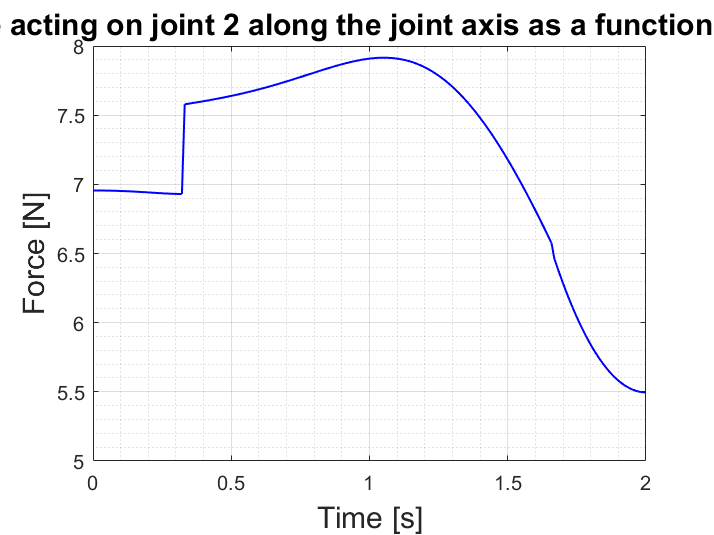

t = linspace(0, T, n);
plot(t,f2(3,:),'b-','linewidth',1)
grid on; grid minor;
xlabel('Time [s]','interpreter','tex','fontsize',15)
ylabel('Force [N]','interpreter','tex','fontsize',15)
title('Force acting on joint 2 along the joint axis as a function of time','fontsize',15)
saveas(gcf, 'q3','png')